# **Interfacing COBRA and *****CellNetAnalyzer***

## Author:  ${Steffen\text{ }Klamt}^1$** and **${\mathbf{Susan Ghaderi}}^2$**: **$^1$ Max Planck Institute for Dynamics of Comple Technical Systems, Magdeburg; $^2$ Systems Biochemistry Group, Luxembourg Centre for Systems Biomedicine 

## Reviewers:

## INTRODUCTION

*CellNetAnalyzer* (CNA) is a MATLAB toolbox for exploring structural and functional pro­per­ties of metabolic, signaling, and regulatory networks. Metabolic networks can be analyzed with stoichiometric and constraint-based modeling techniques, including flux balance analysis (FBA), metabolic flux analysis, elementary-modes analysis, computational strain design (based on minimal cut sets) and others. Signal transduction and (gene) regulatory networks are represented and analyzed as logical networks or interaction graphs but will not be considered herein. CNA can be used either via graphical user interface (GUI) or from command line via an application programming interface (API). In the following we will focus on CNA’s API functions for constrained based modeling of metabolic networks which can easily be interfaced with the COBRA toolbox.  

CNA and the COBRA toolbox have some overlap in their functionality for constraint-based modeling of metabolic networks (e.g., FBA, FVA, etc), however, each tool provides also methods not supported by the other. For example, unique functions of CNA are related to metabolic pathways analysis (calculation of elementary flux modes, elementary flux vectors, convex basis) and computational strain/network design via minimal cut sets. Here we will show how a COBRA model can be converted to a CNA model which can then be analyzed with CNA’s API functions. 

CNA can be downloaded at [http://www.mpi-magdeburg.mpg.de/projects/cna/cna.html](http://www.mpi-magdeburg.mpg.de/projects/cna/cna.html)**. **Follow the instructions for installation and path settings as described in the manual which is distributed along with the software package. An online version of the manual as well as a tutorial can also be found at the CNA web site given above (see links at the end of this document).

In general, interfacing COBRA and CNA is rather simple as they both run under MATLAB and use partially similar model structures. If you have a COBRA model and you would like to use a function of CNA you first have to convert your COBRA model to a CNA model before you can apply API functions of CNA.

## MATERIALS

- *Please ensure that the COBRA Toolbox has been properly installed and initialised. *

- *Also, you should install CNA (CellNetAnalyzer) software and initialise it. CNA web site (with manual): *[https://www2.mpi-magdeburg.mpg.de/projects/cna/cna.html](https://www2.mpi-magdeburg.mpg.de/projects/cna/cna.html) 

## EQUIPMENT SETUP

Requirements for using CellNetAnalyzer are:

- MATLAB Version 7.5 (Release 18) or higher.

- some functions require an LP or (M)ILP solver; CNA supports the optimization toolbox of MATLAB, GLPKMEX, and CPLEX).

- More information can be found on: [https://www2.mpi-magdeburg.mpg.de/projects/cna/cna.html](https://www2.mpi-magdeburg.mpg.de/projects/cna/cna.html) where also a how-to tutorial on CellNetAnalyzer is provided.

## PROCEDURE 

Before you start with CNA *codes*, you should initialise* the *COBRA Toolbox and CNA software by the following commands

initCobraToolbox;

% Add path to Cell Net Analyzer
CNAPath = '~/work/CellNetAnalyzer';
addpath(genpath(CNAPath));
startcna(1)

% Define the COBRA model
global CBTDIR
addpath([CBTDIR filesep 'tutorials' filesep 'additionalTutorials' filesep 'pathVectors'])
load('COBRAmodel.mat')% a simple MATLAB struct with fields defined in the Documentation.
% Define the directory (the place that CNA model will be saved there)
directory = 'Pathwaysvector';

## **Converting a COBRA model to a CNA model**

The next step is the conversion of the COBRA model ‘COBRAmodel’ to a CNA model (project) “cnap” which is achieved by the CNA function “cobra2cna”:

cnap =  CNAcobra2cna(COBRAmodel);

Field 'type' not defined. Initialized with '1' (for mass-flow).
Field 'nums' not defined. Initialized with 6.
Field 'numr' not defined. Initialized with 10.
Field 'specNotes' not defined. Initialized empty 'specNotes'.
Field 'specExternal' not defined. Initialized with zero vector (i.e. all species are configured as internal).
Field 'reacNotes' not defined. Initialized empty 'reacNotes'.
Field 'reacVariance' not defined. Initialized for all reactions a variance level of 0.01.
Field 'reacDefault' not defined. Initialized with NaN vector (empty default values).
Field 'mue' not defined. Initialized according to existence of string 'mue' in 'reacID'.
Field 'reacBoxes' not defined. Initialized with default values.
Field 'macroComposition' not defined. Initialized as empty matrix (no macromolecules defined; other fields related to macromolecules adapted/initialized accordingly).
Field 'epsilon' not defined. Initialized with '1e-10'.
Field 'has_gui' not defined. Initialized with 'false'.


That’s all. With the CNA project variable ‘cnap’ you can now call the API functions of CNA. 

Most fields of the COBRA model have an associated field in the CNA model (e.g. `S ``-> ``stoichMat; lb`` -> ``reacMin; ub``->``reacMax, rxns``->``reacID, mets`` -> ``specID; metNames`` -> ``specLongName` etc.)

## **Relevant API functions of CNA**

Here is a list of most relevant CNA functions for stoichiometric and constraint-based network analysis (the complete set of CNA’s API functions can be found in the directory ../CellNetAnalyzer/code/api and a detailed description is given in the CNA manual):

- **CNAcomputeEFM: **Computes elementary (flux) modes (or, alternatively, a convex basis or elementary flux vectors) from a metabolic network model.

- **CNAcomputeCutsets:** Computes minimal cut sets from given sets of target modes and protected modes.

- **CNAMCSEnumerator:** Computes minimal cut sets via the “dual approach” directly from the network (elementary modes are not needed; can deal with genome-scale networks). See ref [3].

- **CNAregMCSEnumerator: **Similar to CNAMCSEnumerator, computes minimal cut sets via the “dual approach” directly from the network. As an additional feature, up- and downregulation of fluxes is allowed as additional intervention to cuts (knockouts) then yielding *regulatory cut sets* (see ref [4]).

- **CNAgeneMCSEnumerator:** Computes minimal cut sets via the “dual approach” directly from the network similar to CNAMCSEnumerator. But here, true “gene cut sets” (instead of “reaction cut sets) can be calculated (for this purpose, gene-enzyme-reaction associations must be provided).

- **CNAfindRegMCS: **Computes minimal (regulatory) cut sets via the “dual approach” directly from the network similar to CNAregMCSEnumerator. But here only a single cut set is calculated (no enumeration).

- **CNAfluxVariability: **Flux variability analysis.

- **CNAoptimizeFlux:**  Flux balance analysis (optimization of fluxes with respect to a linear objective function).          

- **CNAoptimizeYield:**  Calculates a yield-optimal flux vector maximizing a given yield function (uses linear-fractional programming). 

- **CNAplotPhasePlane:**  Calculates and plots phase planes (or production envelops).  

- **CNAplotYieldSpace:**  Calculates and plots yield spaces.

- **CNAapplyCASOP: **Applies the CASOP strain design method (see ref [1]). 

- **CNAremoveConsRel: **Detects and helps to remove conservation relations from the network (useful for certain calculations).

- **CNAcompressMFNetwork:**  Loss-free compression of a stoichiometric network to a smaller one yielding, for example, the same set of elementary modes.

- **CNAreduceMFNetwork: **Reduction of network to a smaller subnetwork where specified protected functions are maintained (see ref [2]).

- **CNAcna2cobra:**  Converts a (mass-flow) CNA model to a COBRA model.

- **CNAcobra2cna:** Converts a COBRA model to a CNA (mass-flow) model.

## **Example: calculating elementary flux modes of a COBRA model with *****CellNetAnalyzer***

Here we show an example how to calculate elementary flux modes (EFMs) for a COBRA model using an API function of CNA. The metabolic network of COBRAmodel with 10 metabolite (6 internal and four external) and 10 reactions (6 internal and four exchange) looks as follows:

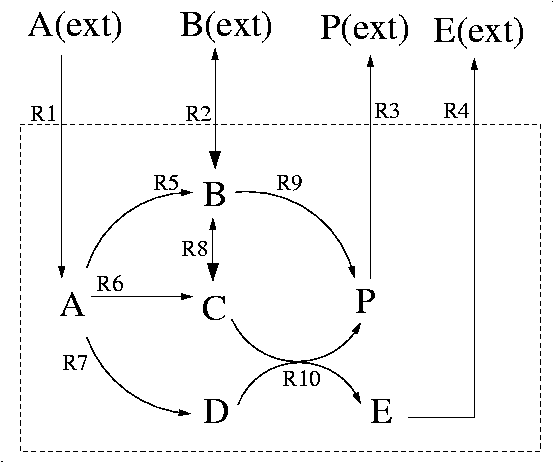

The API function of CNA to calculate elementary flux modes (or, alternatively, elementary flux vectors or convex basis vectors; for a general introduction see [5]) is `CNAcomputeEFM`. 

## Input

Based on computing computing elementary modes and extreme pathways, the inputs can be different. You can see the optional inputs by the command

help CNAcomputeEFM

  CellNetAnalyzer API function 'CNAcomputeEFM'
  ---------------------------------------------
 
  --> Computes elementary (flux) modes / elementary (flux) vectors or a minimal generating set 
      (convex basis) of flux cones or flux polyhedra associated with mass-flow networks. 
      Two different scenarios can be considered: 
      (i) In the homogeneous case, the solution space defined by the steady state assumption and 
          reversibility constraints form a polyhedral (flux) cone. Here, elementary modes can be
          computed which are particular flux vectors of this cone with minimal support 
          (= irreducible set of reactions with non-zero rate). 
          The set of elementary modes includes all extreme rays of the flux cone, but usally many 
          more (support-minimal) vectors. CNAcomputeEFM can also compute a convex basis of the flux cone.
          In contrast to elementary modes, the convex basis is a minimal set of v

 So there are quite a number of different options and arguments. For example, `CNAsolver` can be 0, 1, 3 or 4, which 

- 0: pure Matlab CNA function;

-  1: CNA mex files; 

- 3: Metatool mex files; 

- 4: Marco Terzer's EFMtool (see http://www.csb.ethz.ch/tools/index). 

The Default is 4. Note that EFMtool cannot be used if some reactions are enforced (see constraints) and it cannot be used for calculating the convex basis. 

 However, for a standard calculation of elementary flux modes you just need to call the function with the CNA model (project) variable (which enforces default parameter setting). Hence, enter:

 [efm,rev,idx,ray,efv_with_zero] = CNAcomputeEFM(cnap)

 
 
 
Network compression ...


Can't load log handler "ch.javasoft.util.logging.StandardOutHandler"
java.lang.ClassNotFoundException: ch.javasoft.util.logging.StandardOutHandler
java.lang.ClassNotFoundException: ch.javasoft.util.logging.StandardOutHandler
	at java.net.URLClassLoader$1.run(URLClassLoader.java:366)
	at java.net.URLClassLoader$1.run(URLClassLoader.java:355)
	at java.security.AccessController.doPrivileged(Native Method)
	at java.net.URLClassLoader.findClass(URLClassLoader.java:354)
	at java.lang.ClassLoader.loadClass(ClassLoader.java:425)
	at sun.misc.Launcher$AppClassLoader.loadClass(Launcher.java:308)
	at java.lang.ClassLoader.loadClass(ClassLoader.java:358)
	at java.util.logging.LogManager$4.run(LogManager.java:808)
	at java.security.AccessController.doPrivileged(Native Method)
	at java.util.logging.LogManager.loadLoggerHandlers(LogManager.java:802)
	at java.util.logging.LogManager.initializeGlobalHandlers(LogManager.java:1406)
	at java.util.logging.LogManager.access$1500(LogManager.java:148)
	at jav

 
Matrix size before network compression: 6  10
Matrix size after network compression: 2  6
 
Using 'CalculateFluxModes'
'/Applications/MATLAB_R2016b.app/sys/java/jre/maci64/jre/bin/java' -Xms1024m -Xmx1024m -XX:+UseParallelGC -XX:+UseAdaptiveSizePolicy -XX:+UseAdaptiveGCBoundary -XX:+UseTLAB -XX:+ResizeTLAB -XX:MaxPermSize=20m -cp patch.jar:lib/metabolic-efm-all.jar:lib/dom4j-1.6.1.jar:lib/junit-3.8.1.jar ch.javasoft.metabolic.efm.main.CalculateFluxModes -kind stoichiometry -stoich tmp/stoich.txt -rev tmp/revs.txt -meta tmp/mnames.txt -reac tmp/rnames.txt -arithmetic double -zero 1e-10 -out matlab tmp/efms.mat -compression off -log console -level INFO -tmpdir /Users/susan.ghaderi/work/CellNetAnalyzer/code/ext/efmtool/tmp -maxthreads -1 -normalize min -adjacency-method pattern-tree-minzero -rowordering MostZerosOrAbsLexMin -enforce 

2017-12-20  15:34:34.758  main                     INFO     | =====================================================
2017-12-20  15:34:34.761  main        

efm =      1    -1     0     0     0     1     0    -1     0     0
     1     0     1     0     1     0     0     0     1     0
     1     0     1     0     0     1     0    -1     1     0
     1     1     1     1     0     0     1     1     0     1
     1    -1     0     0     1     0     0     0     0     0
     0     1     1     0     0     0     0     0     1     0
     2     0     1     1     1     0     1     1     0     1
     2     0     1     1     0     1     1     0     0     1


rev =    1
   1
   1
   1
   1
   1
   1
   1


idx =      1     2     3     4     5     6     7     8     9    10


ray =      1     1     1     1     1     1     1     1


efv_with_zero = 1

 In this (standard) case, the EFMs are calculated with efmtool (without inhomogeneous constraints). 

## Output

The output of `pathVectors.m is`

-  `efm`:  contains the elementary flux modes in the rows. The columns contain the stoichiometric coefficients of the reactions - but note that the columns do not necessarily have the same order as in the stoichiometric matrix;

- `idx: `maps the columns in `efm `onto the original columns/reactions, i.e. `idx(i)` maps the `i`-th column (reaction) in `efm` to the column (reaction) number in the stoichiometric matrix (`cnap.stoichmat`). In our example, `idx `exhibits a 1:1 mapping. The vector `rev `indicates the reversibility of the calculated modes (0: reversible; 1: irreversible; hence, in this example, all modes are irreversible);

-  `rev` :  indicates the reversibility of the calculated modes (0: reversible; 1: irreversible; hence, in this example, all modes are irreversible). 

- `ray`:   indicates which of the calculated modes is unbounded (always true for EFMs);

-  `efv_with_zero:` indicates whether the zero vector is part of the solution space (always true for EFMs).

These eoght elementary modes are shown in figuers 2:

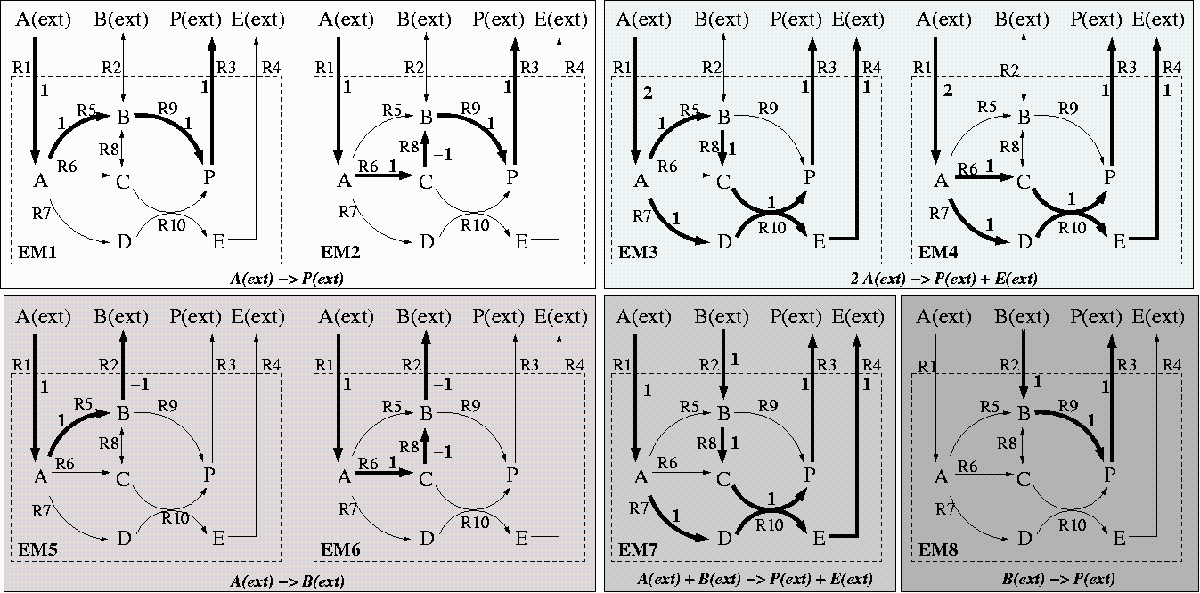

If you now want to calculate the convex basis vectors (a subset of EFMs that are sufficient to span the flux cone; e.g. useful for calculation of extreme pathways) we have to set the `conbasis_flag` argument (the 5-th argument) to `1`. We also choose now the Metatool routine for calculating the convex basis (efmtool cannot be used for calculating convex bases). For the other arguments we chose the standard values:

[efm,rev,idx,ray,efv_with_zero] = CNAcomputeEFM(cnap,[ ],3,1,1)

 
Cannot use METATOOL MEX version: no executable MEX file found
Flux cone is pointed - reversible modes do not exist
 
Remaining metabolites: 2
Remaining reactions: 6 (4 reactions are irreversible)
 
column 1/2: C (6 preliminary vectors, 20-Dec-2017 15:34:36 cput: 0.04
column 2/2: B (5 preliminary vectors, 20-Dec-2017 15:34:36 cput: 0.08
4 convex basis vectors found  20-Dec-2017 15:34:36 cput: 0.09
 
Final number of convex basis vectors: 4
 


efm =      0     1     1     0     0     0     0     0     1     0
     1    -1     0     0     1     0     0     0     0     0
     1     1     1     1     0     0     1     1     0     1
     1    -1     0     0     0     1     0    -1     0     0


rev =      1
     1
     1
     1


idx =      1     2     3     4     5     6     7     8     9    10


ray =      1     1     1     1


efv_with_zero = 1

## **Converting a CNA model to a COBRA model**

A CNA model ‘cnap’ can also be converted to a COBRA model by 

 cbmodel =  CNAcna2cobra(cnap);

Removing 0 external metabolites


Then, COBRA functions can be applied to a (former) CNA model as well.

Note that if you convert a COBRA model to CNA and then back to a COBRA model, some model information can be lost since a CNA model does not capture all (potential) fields of a COBRA model. The following fields will definitely be maintained when converting a COBRA model to a CNA model and back:

- cbmodel.rxns 

- cbmodel.mets

- cbmodel.S

- cbmodel.lb

- cbmodel.ub

- cbmodel.rev

- cbmodel.c

- cbmodel.b

- cbmodel.metNames

## **References**

[1] Hädicke O and Klamt S. (2010) CASOP: A Computational Approach for Strain Optimization aiming at high Productivity. **Journal of Biotechnology,** 147, 88-101. 

[2] Erdrich P, Steuer R, Klamt S. (2015) An algorithm for the reduction of genome-scale metabolic network models to meaningful core models. **BMC Systems Biology** 9:48.

[3] von Kamp A, Klamt S (2014) Enumeration of smallest intervention strategies in genome-scale metabolic networks. **PLoS Computational Biology**, 10:e1003378.

[4] Mahadevan R, von Kamp A, Klamt S. (2015) Genome-scale strain designs based on regulatory minimal cut sets. **Bioinformatics** 31:2844-2851.

[5] Klamt S, Regensburger G, Gerstl MP, Jungreuthmayer C, Schuster S, Mahadevan R, Zanghellini J, Müller S. (2017) From elementary flux modes to elementary flux vectors: Metabolic pathway analysis with arbitrary linear flux constraints. **PLoS Comput Biol** 13:e1005409.